close all; clear; clc; clf;




%



Cd =  [0.15 0.15 0.42 0.25 0.175];
mCd = [0.00 0.60 1.20 1.80 4.000];

drag_at_mach = @(M) interp1(mCd,Cd,M)

drag_at_mach = function_handle with value:
    @(M)interp1(mCd,Cd,M)





% internal_ballistics(N,L_0,r_f,r_i,rho_p,a_0,n)

[mass,chamber,t,accel,velocity,height] = internal_ballistics(4,8,2.375,1,0.065,0.03,0.35)

mass =    30.3242   30.1174   29.9099   29.7018   29.4931   29.2838   29.0738   28.8633   28.6521   28.4404   28.2282   28.0154   27.8020   27.5881   27.3737   27.1587   26.9433   26.7273   26.5109   26.2940   26.0766   25.8587   25.6405   25.4217   25.2026   24.9830   24.7630   24.5427   24.3219   24.1008   23.8793   23.6574   23.4352   23.2126   22.9897   22.7665   22.5430   22.3192   22.0950   21.8706   21.6460   21.4211   21.1959   20.9705   20.7448   20.5189   20.2928   20.0666   19.8401   19.6134


chamber =   190.8853  630.4465  828.2036  881.9534  896.0369  900.9089  903.7036  906.0120  908.1849  910.2997  912.3733  914.4095  916.4092  918.3725  920.2997  922.1908  924.0457  925.8646  927.6475  929.3943  931.1053  932.7803  934.4195  936.0229  937.5905  939.1223  940.6184  942.0788  943.5036  944.8928  946.2464  947.5644  948.8469  950.0939  951.3054  952.4814  953.6221  954.7273  955.7972  956.8318  957.8310  958.7949  959.7235  960.6168  961.4749  962.2978  963.0855  963.8379  964.5552  965.2374


t =          0    0.0530    0.0880    0.1197    0.1507    0.1816    0.2124    0.2432    0.2740    0.3047    0.3354    0.3661    0.3967    0.4273    0.4579    0.4885    0.5191    0.5496    0.5802    0.6107    0.6411    0.6716    0.7020    0.7325    0.7629    0.7932    0.8236    0.8540    0.8843    0.9146    0.9449    0.9752    1.0055    1.0357    1.0660    1.0962    1.1264    1.1567    1.1868    1.2170    1.2472    1.2774    1.3075    1.3376    1.3678    1.3979    1.4280    1.4581    1.4882    1.5183


accel =   -32.2000  -26.3714   14.8993   33.0323   37.4380   38.3619   38.3558   38.0010   37.4334   36.6920   35.7962   34.7630   33.6099   32.3554   31.0185   29.6183   28.1736   26.7020   25.2200   23.7426   22.2831   20.8529   19.4616   18.1170   16.8253   15.5910   14.4173   13.3059   12.2577   11.2724   10.3492    9.4865    8.6822    7.9341    7.2395    6.5955    5.9994    5.4481    4.9387    4.4685    4.0346    3.6344    3.2653    2.9249    2.6111    2.3216    2.0544    1.8078    1.5800    1.3694


velocity =          0   -1.5533   -1.7536   -0.9931    0.1008    1.2708    2.4528    3.6279    4.7878    5.9266    7.0394    8.1217    9.1696   10.1799   11.1497   12.0770   12.9601   13.7981   14.5905   15.3371   16.0385   16.6955   17.3091   17.8807   18.4119   18.9044   19.3601   19.7808   20.1685   20.5252   20.8528   21.1532   21.4283   21.6797   21.9091   22.1183   22.3086   22.4814   22.6383   22.7802   22.9085   23.0241   23.1281   23.2214   23.3048   23.3791   23.4450   23.5031   23.5541   23.5985


height =          0   -0.0412   -0.0989   -0.1425   -0.1564   -0.1352   -0.0778    0.0158    0.1452    0.3098    0.5088    0.7414    1.0064    1.3027    1.6291    1.9843    2.3669    2.7756    3.2088    3.6652    4.1433    4.6419    5.1594    5.6947    6.2464    6.8134    7.3944    7.9884    8.5943    9.2112    9.8382   10.4743   11.1189   11.7711   12.4303   13.0958   13.7670   14.4435   15.1247   15.8101   16.4993   17.1920   17.8877   18.5862   19.2871   19.9901   20.6951   21.4017   22.1098   22.8191


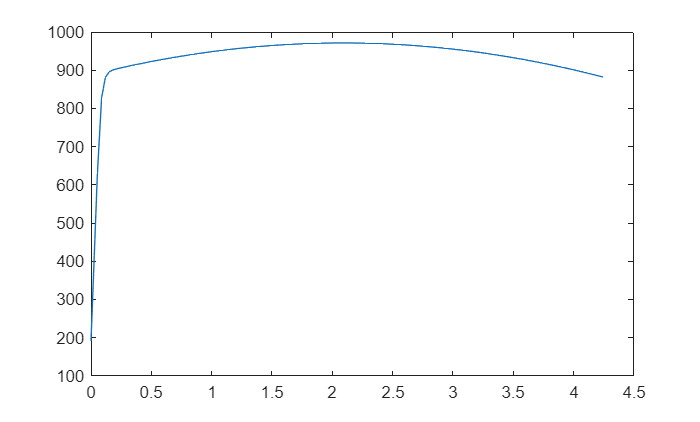

plot(t,chamber)

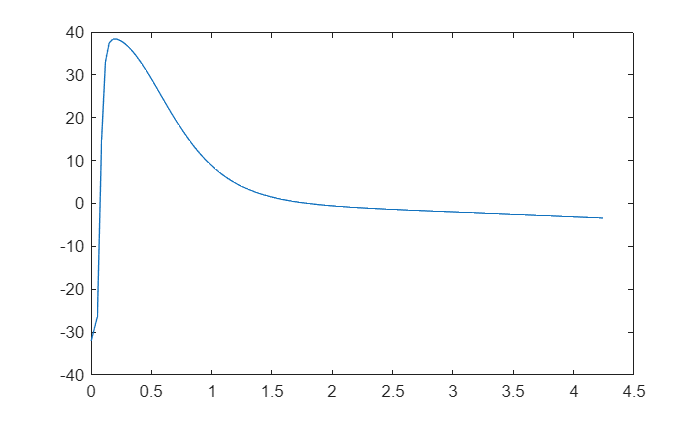

plot(t,accel)

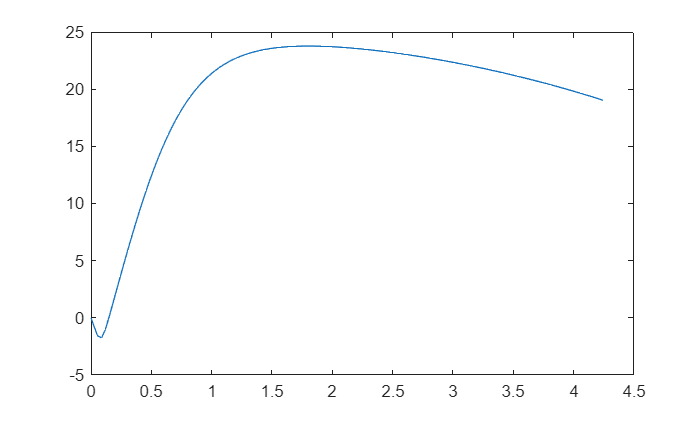

plot(t,velocity)

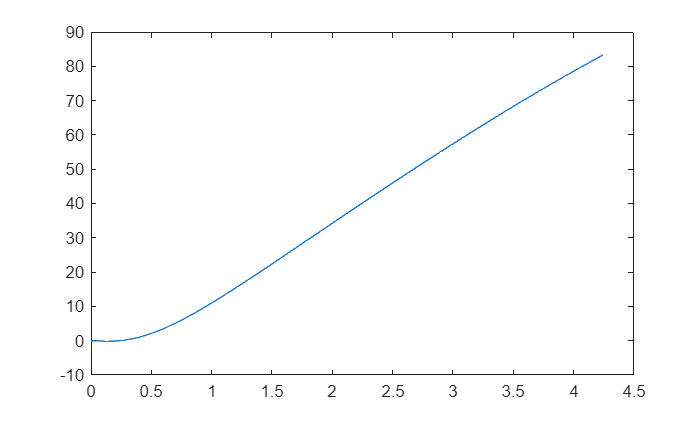

plot(t,height)



function [mpropelent,pressure_chamber,time,acc,vel,height] = internal_ballistics(N,L_0,r_f,r_i,rho_p,a_0,n)

cstar = 5210;
w_step = 0.01;
w(1) = 0;
pressure_chamber(1) = (rho_p*a_0*N * 2*pi*( r_f^2 - (r_i).^2 + (r_i).*L_0)*cstar)^(1/1-n);
time(1) = 0;
A_t(1) = 1;
exit_area = 4;
gamma = 1.25;

acc(1) = -32.2;

vel(1) = 0;

height(1) = 0;

cf(1) = 1.5;



temp_amb(1) = 518;
ambient_pressure(1) = 14.69241;

Cd =  [0.15 0.15 0.42 0.25 0.175];
mCd = [0.00 0.60 1.20 1.80 4.000];

rho_air(1) = 0.07579;

m_i = rho_p * N * pi*(r_f^2 - r_i^2) * (L_0) + N*(L_0 + 0.125) * 0.25 + 40 + 1;

for iteration = 1:1000

w(iteration + 1) = 0 + w_step*iteration;

A_b(iteration) = N * 2*pi*( r_f^2 - (r_i+w(iteration)).^2 + (r_i+w(iteration)).*(L_0 - 2.*w(iteration)));

r(iteration) = a_0 * (pressure_chamber(iteration))^n;

dt = w_step/r(iteration);

A_t(iteration+1) = ((4/pi)^0.5 + 0.000087 * dt*pressure_chamber(iteration))^2*pi/4;


pressure_chamber(iteration + 1) = (rho_p * r(iteration)*A_b(iteration)*cstar/A_t(iteration))^(1/1-n);

time(iteration+1) = time(iteration) + dt;

mpropelent(iteration) = rho_p * N * pi*(r_f^2-(r_i+w(iteration))^2) * (L_0 - 2*w(iteration));

arearatio = exit_area / A_t(iteration);


mach = abs(vel(iteration)/sqrt(1.4*1545.3/28.97*32.2*temp_amb(iteration)));

acc(iteration+1) = cf(iteration) * A_t(iteration) * pressure_chamber(iteration)/(m_i - mpropelent(iteration)) -32.2 - interp1(mCd,Cd,mach)*32.2*(0.5*rho_air(iteration)*vel(iteration)^2)*(pi*r_f^2)/(m_i - mpropelent(iteration));

temp_amb(iteration+1) = -0.0036 * height(iteration) + 518; 

rho_air(iteration+1) = (0.00000000001255)*vel(iteration)^2 -(0.0000019453)*vel(iteration) + 0.07579;

vel(iteration + 1) = (acc(iteration+1) + acc(iteration))/2 * dt + vel(iteration);

height(iteration + 1) = (vel(iteration + 1) + vel(iteration)) /2 * dt+ height(iteration);

pcOverpa = pressure_chamber(iteration)/ambient_pressure(iteration);
papc = pcOverpa^(-1);
pepc = (1+(gamma-1)/2 * mach^2)^((gamma-1)/gamma);


cf(iteration+1) = (2*gamma^2/(gamma-1)   *   (2/(gamma+1))^((gamma+1)/(gamma-1))   *   (1 - (pepc)^((gamma-1)/gamma))) + (pepc-papc)*arearatio;


ambient_pressure(iteration + 1) = -4.272981*10^(-14) * height(iteration)^3 + 0.000000008060081*height(iteration)^2 + 0.0005482655*height(iteration) + 14.69241;


if (r_i + w(iteration)) >= r_f  
    break;
elseif (L_0 - 2*w(iteration)) <= 0
    break;
end

end
% for iteration = 1:1000
% 
% mach = abs(vel(iteration)/sqrt(1.4*1545.3/28.97*32.2*temp_amb(iteration)));
% 
% acc(iteration + 1) =  -32.2 - interp1(mCd,Cd,mach)*32.2*(0.5*rho_air(iteration)*vel(iteration)^2)*(pi*r_f^2)/(m_i - mpropelent(end));
% 
% vel(iteration + 1) = (acc(iteration+1) + acc(iteration))/2 * dt + vel(iteration);
% 
% height(iteration + 1) = (vel(iteration + 1) + vel(iteration)) /2 * dt+ height(iteration);
% 
% rho_air(iteration + 1) = (0.00000000001255)*vel(iteration)^2 -(0.0000019453)*vel(iteration) + 0.07579;
% 
% temp_amb(iteration + 1) = -0.0036 * height(iteration) + 518; 
% 
% 
% 
% 
% end

end


